# Asesoria

### Metodos Numericos

#### 2022-2S : 02/09/2022

Particular example, use of symbolics

### Quantum Mechanics

*Expected values and standard deviation for position of a particle in an infinite square potential*

clear
syms psi(x)
syms x n L real

psi(x) = sqrt(2 / L) * sin(pi * x / L)

$$psi(x) = \sqrt{2}\,\sin\left(\frac{\pi \,x}{L}\right)\,\sqrt{\frac{1}{L}}$$

xbar = simplify(int(psi^2 * x, [0, L]))

$$xbar = \frac{L}{2}$$

x2bar = simplify(int(psi^2 * x^2, [0, L]))

$$x2bar = \frac{L^{2}\,\left(2\,\pi^{2}-3\right)}{6\,\pi^{2}}$$

nx2barexpr = (L^2*(2*n^2*sym(pi)^2 - 3))/(6*n^2*sym(pi)^2)

$$nx2barexpr = \frac{L^{2}\,\left(2\,n^{2}\,\pi^{2}-3\right)}{6\,n^{2}\,\pi^{2}}$$

sigmax = simplify(sqrt(x2bar - xbar^2))

$$sigmax = \frac{\sqrt{3}\,\left|L\right|\,\sqrt{\pi^{2}-6}}{6\,\pi }$$

nsigmaexpr = simplify(sqrt(nx2barexpr - xbar^2))

$$nsigmaexpr = \frac{\sqrt{3}\,\left|L\right|\,\sqrt{n^{2}\,\pi^{2}-6}}{6\,\pi \,\left|n\right|}$$

asintote = limit(nsigmaexpr, n, inf)

$$asintote = \frac{\sqrt{3}\,\left|L\right|}{6}$$

clear

A = [8 1 1 0; 6 7 -1 1; 1 0 3 0; 0 3 0 4];
[~] = Jac_GS(A)

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 0.5000

ratioTGS = 0.2616

ratioTw = 0.2616

clear

format short

clear
syms V(h)
syms h real

V0 = .75; r = 1;
V(h) = pi * h^2 * (3 * r - h) / 3;

g_A(h) = (3 * (r * h^2 - V0 / pi))^(1/3);
g_B(h) = sqrt((h^3 + 3*V0 / pi) / (3*r));

clf('reset')
hold on
fplot(g_A, [0, 1], 'DisplayName', 'g_A(h)')
fplot(g_B, [0, 1], 'DisplayName', 'g_B(h)')
fplot(h, [0, 1], 'DisplayName', 'y = x')
xline(.55, 'DisplayName', 'x = .55')
legend('Location','best')
grid on
hold off

clear
syms g(x)

g(x) = (4 * x^3 + 2)/14;

clf('reset')
hold on
fplot(g, [-2, 2], 'DisplayName', 'g_B(h)')
fplot(x, [-2, 2], 'DisplayName', 'y = x')
legend('Location','best')
grid on
hold off
P = [4 0 -14 2]; R = sort(roots(P))
dg = diff(g, x);
eval(dg(R)), eval(dg(-1.5))
g = matlabFunction(g);
c = fixpt(g, -1.5, 1e-15, 100)

clear
syms f(x)

f(x) = (exp(cos(2*x)) - 1)* sin(x - pi/4)
df(x) = diff(f, x)
clf('reset')
hold on
fplot(f, [0, 5], 'DisplayName', 'f(h)')
fplot(df, [0, 5],'-.', 'DisplayName', 'df(h)')
yline(0, 'DisplayName', 'y = 0')
legend('Location','best')
grid on
hold off

clear

A = [4 -1 0 0; -1 4 -2 0; 0 -1 4 -1;-3 0 -1 5];

D = diag(diag(A))
L = - tril(A, -1)
U = - triu(A, 1)
TJ = D \ (L + U)
b = [4 3 3 4]';
D^-1 * b
norm(TJ, 'inf')
[TJ] = Jac_GS(A), norm(TJ, 2), norm(TJ)

clear

A = [.8 .3; .2 .7];
[V D] = eigs(A);

clear

syms g(x) [1 3]

g1(x) = x + 1/ 2 * (exp(-x) - cos(3*x));
g2(x) = 1/3 * acos(exp(-x));
g3(x) = x - 1/ 3 * (exp(-x) - cos(3*x));

clf('reset')
hold on
fplot(g1, [0 5], 'DisplayName', 'g_1(x)')
fplot(g2, [0 5], 'DisplayName', 'g_2(x)')
fplot(g3, [0 5], 'DisplayName', 'g_3(x)')
fplot(x, [0 5], 'DisplayName', 'y = x')
grid on
legend('Location','best')
hold off
clf('reset')
hold on
fplot(g1, [2.4 2.6], 'DisplayName', 'g_1(x)')
fplot(g3, [2.4 2.6], 'DisplayName', 'g_3(x)')
fplot(x, [2.4 2.6], 'DisplayName', 'y = x')
grid on
legend('Location','best')
hold off
dg1(x) = diff(g1, x);
dg3(x) = diff(g3, x);
c = 2.4;
eval(dg1(c)), eval(dg3(c))
g1 = matlabFunction(g1); g2 = matlabFunction(g2); g3 = matlabFunction(g3);

k = fixpt(g1, c, 1e-15, 100), k = fixpt(g2, c, 1e-15, 100), k = fixpt(g3, c, 1e-15, 100)

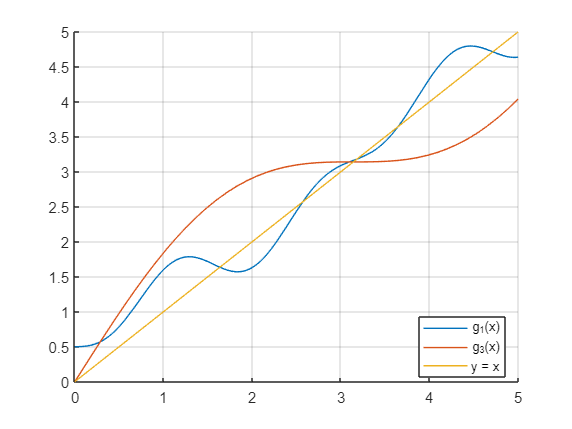

format long
syms g(x) [1 3]

g1(x) = x + 1/ 2 * (exp(-x) - sin(x)*cos(3*x));

g3(x) = x + sin(x);

clf('reset')
hold on
fplot(g1, [0 5], 'DisplayName', 'g_1(x)')
fplot(g3, [0 5], 'DisplayName', 'g_3(x)')
fplot(x, [0 5], 'DisplayName', 'y = x')
grid on
legend('Location','best')
hold off

g3 = matlabFunction(g3);
c = fixpt(g3, 3, 1e-15, 100)

c =    3.141592653589793


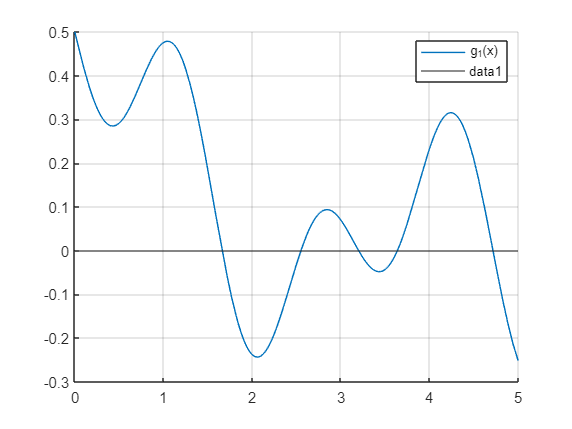

clear
syms g(x) [1 3]

g1(x) = 1/ 2 * (exp(-x) - .7*sin(x)*cos(3*x));

clf('reset')
hold on
fplot(g1, [0 5], 'DisplayName', 'g_1(x)')
yline(0)
grid on
legend('Location','best')
hold off

Revisión comentarios de Sebastian.

% Verifiquemos las siguientes hipotesis
% Hallemos los ceros de f(x), y verifiquemos si pueden
% ser reales para fog(x)
P = [1 -5 5 9 -14 -4 8]; % Coeficientes
R = roots(P)

R =   -1.0000 + 0.0000i
  -1.0000 - 0.0000i
   2.0000 + 0.0000i
   2.0000 - 0.0000i
   2.0000 + 0.0000i
   1.0000 + 0.0000i


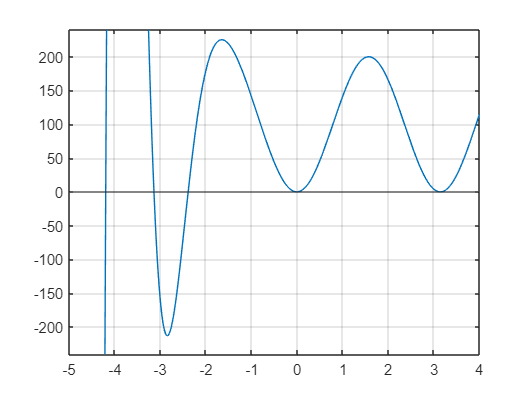

clear
syms h(x)

h(x) = exp(-2*x) * sin(3*x) - 100*cos(2*x) + 100;

clf('reset')
fplot(h, [-5, 4])
ylim(240*[-1, 1])
yline(0)
grid on

Verifiquemos que los puntos que parecen raices multiples si lo sean.

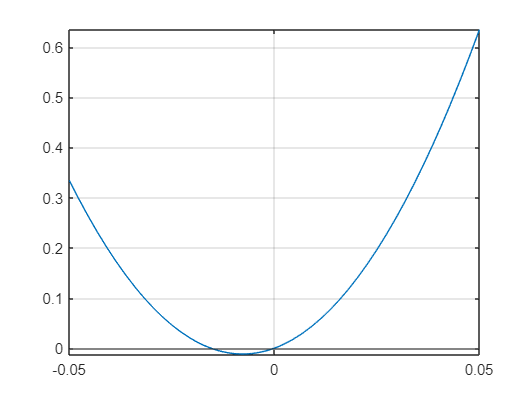

clf('reset')
fplot(h, [-.05, .05])
yline(0)
grid on

Veamos que se trata de 2 ceros simples.

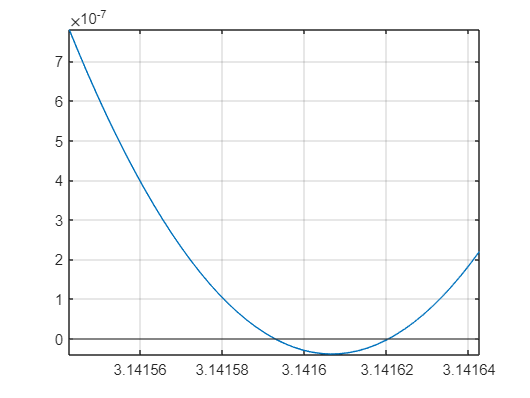

clf('reset')
fplot(h, [pi-.00005, pi+.00005])
yline(0)
grid on